# Non linear behaviours and control of a conical tank system

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of more complex components and connections. In such cases writing code can be messy or difficult and it is often easier to capture the scenario using tools such as simulink.

This livescript focusses on a conical tank system which is characterised by significant non-linear dynamics. The main aim of these resources are to demonstrate and understand the impact of this non-linearity on behaviour and control. For completeness, other non-linear components can also be included, for example actuation limits,  output pipe blockages and measurement noise.

The basis of this resource are two simulink files ***conical_tank_system_control101.slx, conical _tank_system_fbk_control101.slx***.  Take a copy in your own area if you want to edit these for further study. Code to run the simulation and define the settings is given in the sections below, but the easiest way to interact initially is through the app file:***conical_tank_behaviour_control101.mlapp. ***

The simulink files were built with MATLAB version 2023 so will not work on earlier versions.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox) 

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Preamble

Many simulink files have a large number of parameters which are most conveniently defined with a supporting MATLAB script and thus one might as well run the simulink file directly from the same script, as shown below. This resource collects the core parameter values from the workspace and a step input component, runs the simulation and then the outputs are sent back to the workspace for plotting.

To modify the simulink diagrams and other details, make a copy into your own area first.

## Table of contents

- Simple hydraulic system model for a conical tank

- Open-loop simulation of a conical tank model: linear and non-linear

- Introducing feedback

- The app files

## 1. Simple hydraulic system model for a conical tank

### 1.1 A conical tank

A conical tank system is taken to have a controllable flow into the tank, for example from the top, and an outflow that depends upon the depth. A schematic is given in Figure 1.1. 

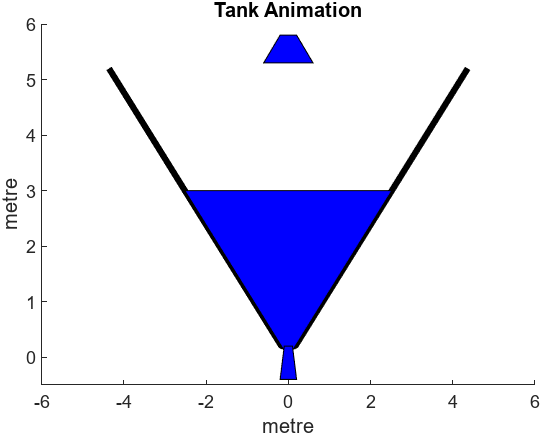

**Figure 1.1 **A conical tank system

Let *P* be atmospheric pressure, *A* the cross-sectional area, *h* the  depth. The input flow depends upon an input signal *u* through a gain, that is: $q_i =k_p u$ and the outlet flow depends upon the presssure difference across the outlet pipe and some constant *R* (which reflects the area of the pipe, etc.). Simple modelling equations are common in the textbooks, as follows:

$\frac{d\;V}{\textrm{dt}}=q_i -q_o ;\;\;\;\;\;\;\;\;q_o =\frac{1}{R}\sqrt{\left(p-p_o \right)};\;\;\;\;\;\;\;\;\;\;\;\left(p-P\right)=\rho g\;h$;        $C=\frac{\rho g}{R\;A}$      (1)

For a conical tank, the volume is:   $V=\frac{1}{3}\pi h^3 \tan^2 \left(\theta \right)$, where the radius at any given depth is $r=h\;\tan \left(\theta \right)$.

Hence the model becomes:

$\frac{d\;V}{\textrm{dt}}=q-\frac{1}{R}\sqrt{\rho \;g\;h}$        or         $\frac{d\;h}{\textrm{dt}}=\frac{1}{{\pi h}^2 \tan^2 \left(\theta \right)}\left\lbrack q-\left(\frac{\sqrt{\rho g}}{R}\right)\sqrt{\;h}\right\rbrack$

### 1.2 Linearised model (for a given steady-state depth)

Define the steady-state operating point as: $h_{\textrm{ss}} ,q_{\textrm{ss}} ,{\;\;\textrm{with}\;\;\;\;p}_{\textrm{ss}} =\rho g\;h_{\textrm{ss}} +P,{\;\;\;\;\;\;\;\;q}_{\textrm{ss}} =\frac{1}{R}\sqrt{\left(p_{\textrm{ss}} -p_o \right)}$ where *p* is the pressure at the bottom of the tank and $p_o$ the pressure at the end of the outflow,  *h* is the depth and *R* a constant that depends on the outflow pipe parameters. For convenience here, assume that: $P=p_o \ldotp$ 

Next express the non-linear term as a Taylor series around the steady-state: $\left(p_{\textrm{ss}} -P\right)=\rho g\;h_{\textrm{ss}}$, $q_{\textrm{ss}=} \frac{1}{R}\sqrt{\rho \;g\;h_{\textrm{ss}} }$. With linear systems, it is common to linearise around a given operating point and so that is what will be done here, although the simulink file will continue to use the full non-linear model. Deviations are usually taken relative to a steady-state, so for example:


$$\hat{h} =h-h_{\textrm{ss}} ,\hat{q} =q-q_{\textrm{ss}}$$


Linearisation is often performed using a 1st order Taylor series.

Hence:                  $\frac{d\;h}{\mathrm{dt}}=\frac{1}{{\pi h}^2 \tan^2 \left(\theta \right)}\left\lbrack q-\left(\frac{\sqrt{\rho g}}{R}\right)\sqrt{\;h}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{d\;\hat{h} }{\mathrm{dt}}=\alpha \hat{q} +\beta \hat{h}$    (2)

where $\alpha =\frac{d}{\textrm{dq}}\left(\frac{1}{{\pi h}^2 \tan^2 \left(\theta \right)}\left\lbrack q-\left(\frac{\sqrt{\rho g}}{R}\right)\sqrt{\;h}\right\rbrack \right);\;\;\beta =\frac{d}{\textrm{dh}}\left(\frac{1}{{\pi h}^2 \tan^2 \left(\theta \right)}\left\lbrack q-\left(\frac{\sqrt{\rho g}}{R}\right)\sqrt{\;h}\right\rbrack \right)\;$with derivatives evaluated at the operating point. Thus:

$\alpha =\left(\frac{1}{{\pi h}_{\textrm{ss}}^2 \tan^2 \left(\theta \right)}\right)$;    $\beta =-\left(\frac{2}{{\pi h}_{\textrm{ss}}^3 \tan^2 \left(\theta \right)}\right)q_{\textrm{ss}} +\left(\frac{1\ldotp 5}{{\pi h}_{\textrm{ss}}^{2\ldotp 5} \tan^2 \left(\theta \right)}\right)\left(\frac{\sqrt{\rho g}}{R}\right)$

In transfer function format one can write the linearised model as:


$$\hat{H} \left(s\right)=\frac{\alpha }{s+\beta }\hat{Q} \left(s\right)=G\left(s\right)\hat{Q} \left(s\right);\;\;\;\;\;\;\;\;G\left(s\right)=\frac{\alpha }{\;s+\beta }$$
 

or in state space form: $A=\beta ,B=\alpha ,C=1\ldotp$

## 2 Open-loop simulation of a conical tank model: linear and non-linear

A simulink file is created to capture both the non-linear (top blocks) and linear (lower blocks) model above (eqns. (1,2)); Figure 1.2 shows the simulink diagram. 

- The file allows for blockages of the outlet pipe which in essence are done as a percentage so:  $R\to \left(1-\nu \right)R,$ where $\nu$ is the percentage blockage.

- Disturbance flows add directly to the controllable input flow but are assumed unknown.

- The initial steady-state input flow defines the assumed operating point.

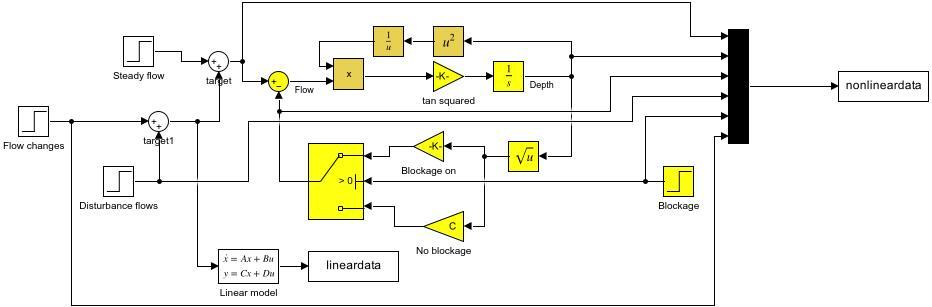

**Figure 1.2 **Screen capture of the simulink file ***conical_tank_system_behaviour_control101_2023.slx***

### 2.1 MATLAB code for a simulation

The code snippet below shows which data needs to be defined in order to run the simulation; it should be self-evident therefore how to make changes in order to perform individual investigations. It will be clear immediately that the non-linear model behaves differently as soon as one moves away from the linearisation point and obviously, any blockage causes a huge difference compared to the orginal linear model. The linear model uses deviation variables relative to the linearisation point.

disp('*****************************')

*****************************


disp('Section 2 illustrations below')

Section 2 illustrations below



% to open simulink file use the line below
%   open conical_tank_system_behaviour_control101_2023.slx  

% Simulation parameters
blocksize = 0.2;  % size of blockage as percentage
qstep = 0.005;     % change in inflow compared to steady-state
endtime=4200;     % simulation run time
blockagetime=3000; % time that blockage introduced
qchangetime = 200; % time that change in flow introduced
disturbanceflowtime =1200;
disturbanceflow =0.001;

% Model parameters needed by simulink file
rho=1000;    % water density
g=10;        % gravity
tantheta = 1;  % angle of tank
tantheta2=tantheta^2*pi;
itantheta2  =1/tantheta2;
hss = 1;  % notional depth for initialisation
R=10^4;      % constant needed to determine outflow
C=sqrt(rho*g)/R;
Ctemp = C*(1-blocksize);  % Increase R during blockage which reduces outflow
qss = C*sqrt(hss);  % steady-state inflow to achieve the initialisation depth

% Linear model
alpha = 1/(hss^2*tantheta2);
beta = -(2/(hss^3*tantheta2))*qss + C*1.5/(hss^2.5*tantheta2);

% Simulation - results will appear in the figures
sim("conical_tank_system_behaviour_control101_2023.slx");

Model 'conical_tank_system_behaviour_control101_2023' was exported from R2024a to R2023b. To find blocks that were removed during the export operation, click here. Save the model to remove this notification.


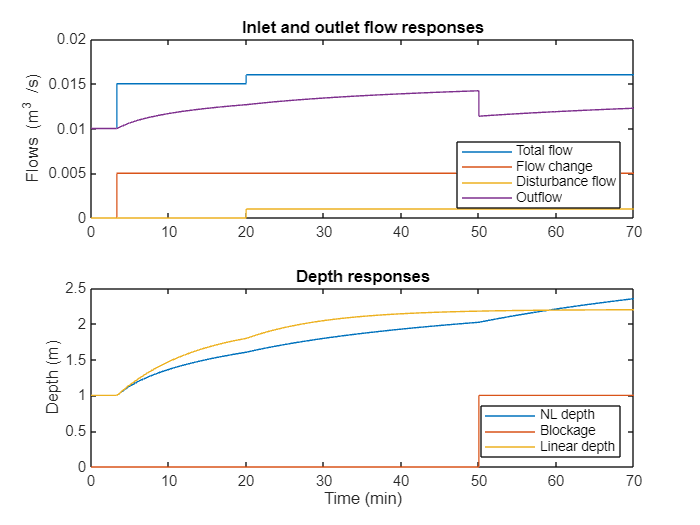

tt=nonlineardata.time;
ttl=lineardata.time;
yy = nonlineardata.signals.values; % stored in order as shown in Figure 1.3
yl = lineardata.signals.values; % stored in order as shown in Figure 1.3

% Plotting
subplot(211)
plot(tt/60,[yy(:,[1,6,4,3])]);
legend('Total flow','Flow change','Disturbance flow','Outflow','Location','southeast')
title('Inlet and outlet flow responses')
ylabel('Flows (m^3 /s)')
subplot(212)
plot(tt/60,yy(:,[2,5]),ttl/60,yl+hss);
legend('NL depth','Blockage','Linear depth','Location','southeast')
ylabel('Depth (m)')
xlabel('Time (min)')
title('Depth responses')

% xlim([3.3 3.5])
% ylim([0.99,1.01])

%print(['-sconical_tank_system_behaviour_control101_2023'],'-djpeg',['conical_tank_system_behaviour_control101_2023.jpg'])

**Experiments: **Try changing the linearisation point (that is the initial depth), the angle of the tank, the value for *R* and the various steps sizes and observe the differences between the lienarised model (linearised at the initial depth) and the non-linear model behaviour. Also notice how the differences vary depending on the initial depth.  To what extent do you think the linearised model is valid and useful?

### 2.2 Virtual laboratory

It is somewhat tedious to interact with MATLAB code such as that above, hence a virtual laboratory interface has been produced so that users can investigate the behaviour of the tank using sliders and buttons.  This interface is discussed in section 4 below.

### 2.3 The impact of parameterisation errors

The current simulation is not designed to support a study of the impact of parameterisation errors although this would be straightforward to do by using different values for theta and *R* in the definition of the linear model, and indeed misaligning the choice of the linearisation point. Interested users can easily modify the simulink file to code in modelling errors, although as this section is focussing on open-loop behaviours, that is likely an unnecessary complication. Clearly the blockages are one form of parameterisation error which is easy to include and one can vary the blocksize as desired.

## 3 Introducing feedback

Ultimately we would like to control the depth in the tank, not withstanding the uncertainty and non-linearity. This resource will use simple PI compensation as derivative is not usually needed for 1st order systems. The focus will be on real issues that can impact on the behaviour, for example:

- What is the impact of the non-linearity?

- What happens when the in-flow is constrained?

- What happens when depth measurement is noisy?

- What happens with temporary blockages.

- What happens with temporary disturbance in flows?

Using simulink means that these issues can be absorbed neatly and cleanly. 

It would be usual to design and implement the PI compensator on the deviation variables so the simulink file should define these clearly.

### 3.1. Nominal PI design

The design of the PI compensator is done using the linearised model, but thereafter the non-linear model is used for performance evaluation.  Consider a steady-state depth of $h_{\textrm{ss}} \;$as the notional point. The linearised model (as shown in section 1) is given as:

 
$$\hat{H} \left(s\right)=\frac{\alpha }{\;s+\beta }\hat{Q} \left(s\right)=G\left(s\right)\hat{Q} \left(s\right);\;\;\;\;\;$$


Consequently, a simple heuristic PI design (see [https://controleducation.sites.sheffield.ac.uk/chapterfeedbackintro/sectionfbkpid)](https://controleducation.sites.sheffield.ac.uk/chapterfeedbackintro/sectionfbkpid)) is given as:


$$M\left(s\right)=K_p +\frac{K_i }{s};\;K_p =\frac{\beta }{\alpha };\;K_i =\frac{\beta^2 }{\alpha }$$


The expected responses can be determined using very simple code based on the linearised model and these evidence that, in the region of the linearisation point, this PI is effective. The design has been chosen to give a closed-loop input that does not over actuate.

disp('*****************************')
disp('Section 3.1 illustrations below')
% Model parameters needed by simulink file
rho=1000;    % water density
g=10;        % gravity
R=10^4;      % constant needed to determine outflow
C=sqrt(rho*g)/R;
tantheta = 0.8;  % angle of tank
tantheta2=tantheta^2;
hss = 1;  % notional depth for initialisation
qss = C*sqrt(hss);  % steady-state inflow to achieve the initialisation depth
alpha = 1/(hss^2*tantheta2);
beta = -(2/(hss^3*tantheta2))*qss + C*1.5/(hss^2.5*tantheta2);
G=tf(alpha,[1,-beta]);   % linearised model

*****************************


M = (-beta/alpha)*tf([1,-beta],[1 0]);  % Heuristic PI compensator

Section 2.1 illustrations below



% Closed-loop simulations and plotting
[y,t]=step(feedback(G*M,1));
u=step(feedback(M,G),t);
subplot(211)
plot(t/60,y)
legend('Depth')
xlabel('time (min)')
title('Closed-loop responses on a linearised model (deviation variables)')
subplot(212)
plot(t/60,u); ylim([0,max(u)*1.1])
legend('Input flow')
xlabel('time (min)')

### 3.2 The simulation environment

Next it is necessary to define a simulink model containing all the real issues that might be expected. This is given in Figure 2 below where the measurement noise,   input saturation, disturbance in-flow  and blockages should be evident. Open the simulink file (*open conical_tank_system_control101_2023.slx*) and double click on the conical tank block to see more details of the coding of the tank, although in essence this is copied from Figure 1 above.

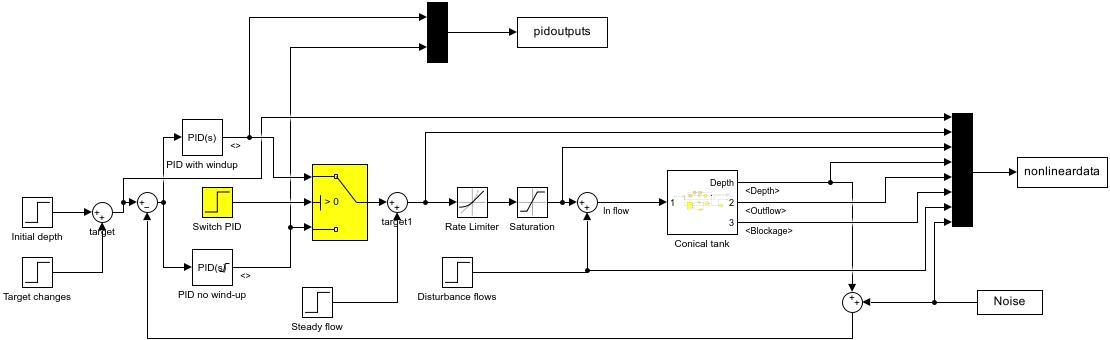

**Figure 2**. Simulink diagram of closed-loop control of a non-linear tank system (***conical_tank_system_control101.slx***)

The reader can set the timing and magnitude of the desired uncertain affects through a simple code snippet, as illustrated next, and thus carry out systematic investigations.  The PI design as given in section 2.1 is used based on the initial depth.

- Change umax, Dumax and Dumin to observe impact of input limits on behaviour. Note that if umax is too small, integral saturation will occur if the control coding does not recognise and correct for this. 

- The impact of measurement noise is transparent in the output curves.

- The closed-loop rejects blockages, as long as there is sufficient control freedom to do so.

- The closed-loop will reject disturbance in-flows, if there is sufficient freedom to do so.

- Anti-windup is an option as users may to want to investigate this concept. **Open the PID block to explore some anti-windup options **

- Notice how the efficacy of the PI is good near the linearisation point, but less so for larger target changes where the non-linear model is now significantly different.

One might also choose to overlay the nominal responses expected with the linearised model to give a point of comparison although that is not done here as non-trivial and is left as a task for interested users: duplicate the simulink file and replace the non-linear conical tank model with a linear one.

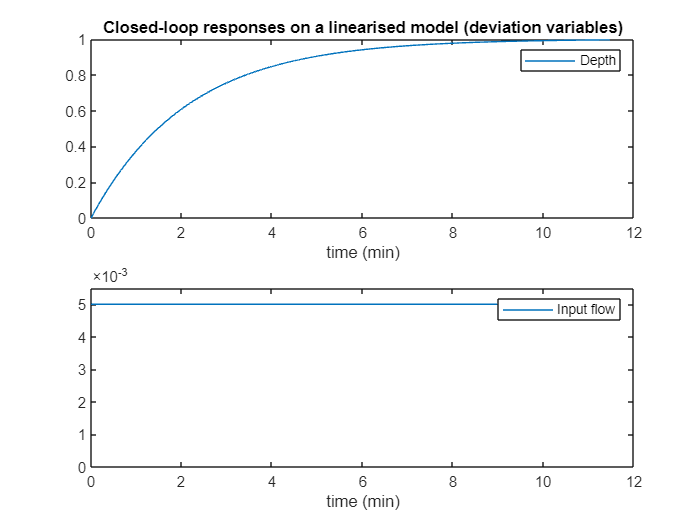

disp('*****************************')
disp('Section 3.2 illustrations below')
% open conical_tank_system_control101_2023.slx
%print(['-sconical_tank_system_control101_2023'],'-djpeg',['conical_tank_system_control101_2023.jpg'])

% Simulation parameters
endtime=4200;     % simulation run time
Initial_depth = 1;
Targetchange = 0.5;
Targetchangetime = 200;
Noise=[];

Noise(:,1) = [0:endtime]';
Noise(:,2)=randn(1,endtime+1)'/100;    % magnitude of measurement noise
disturbanceflowtime=800;
disturbanceflow=0.002;
switchpidtime=0;   % With or without anti-windup
switchpid=1;       % no anti windup
blocksize = 0.2;  % size of blockage as percentage
blockagetime=2400; % time that blockage introduced
disturbanceflowtime =1200;

*****************************


disturbanceflow =0.002;

Section 2.2 illustrations below



% Model parameters needed by simulink file
rho=1000;    % water density
g=10;        % gravity
tantheta = 0.8;  % angle of tank
tantheta2=tantheta^2*pi;
itantheta2=1/tantheta2;
hss = Initial_depth;  % notional depth for initialisation
R=10^4;      % constant needed to determine outflow
C=sqrt(rho*g)/R;
Ctemp = C*(1-blocksize);  % Increase R during blockage which reduces outflow
qss = C*sqrt(hss);  % steady-state inflow to achieve the initialisation depth

Dumax = 0.0001;    % rate limits on input
Dumin = -0.0001;
umax = 0.03;      % absolute limits on the input
umin = 0;

% Linear model
alpha = 1/(hss^2*tantheta2);
beta = -(2/(hss^3*tantheta2))*qss + C*1.5/(hss^2.5*tantheta2);
Kp = (-beta/alpha);
Ki = -Kp*beta;

% Simulation - results will appear in the scope
sim("conical_tank_system_control101_2023.slx");
tt=nonlineardata.time;
yy = nonlineardata.signals.values; % stored in order as shown in Figure 2


% Plotting
subplot(211)
plot(tt/60,[yy(:,[1,4]),yy(:,4)+yy(:,8),yy(:,6)*blocksize]);
legend('Target','True Depth','Measured depth','Blockage','Location','southeast')
title('Inlet and outlet flow responses')
ylabel('Depth (m)')
%yy(:,7)*blocksize

subplot(212)
plot(tt/60,[yy(:,[2:3,5,7])]);
legend('Desired flow','Controlled flow','Out flow','Disturbance flow','Location','southeast')
ylabel('Flows (m^3 /s)')
xlabel('Time (min)')
title('Input responses')

### 3.3 Illustration of systematic investigations

It is straightforward to run the file above with a number of different settings and produce overlay plots to investigate different effects. This is illustrated here concisely, but left to the reader to take further. Assume section 3.2 above has already been run so that most system data is already defined.

disp('Section 2.3 illustrations below')

Model 'conical_tank_system_control101_2023' was exported from R2024a to R2023b. To find blocks that were removed during the export operation, click here. Save the model to remove this notification.


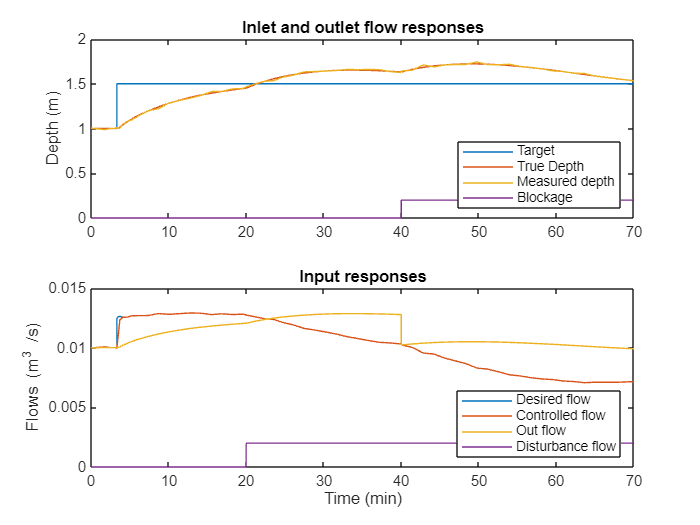


% Simulation 1
Dumax = 0.0001;    % rate limits on input
Dumin = -0.0001;
sim("conical_tank_system_control101_2023.slx");
tt1=nonlineardata.time;
yy1 = nonlineardata.signals.values; % stored in order as shown in Figure 2

% Simulation 2 (same as simulation 1 but tighter rate limits)
Dumax = 0.00002;    % rate limits on input
Dumin = -0.00002;
sim("conical_tank_system_control101_2023.slx");
tt2=nonlineardata.time;
yy2 = nonlineardata.signals.values; % stored in order as shown in Figure 2

% Simulation 3 (same as simulation 2 but larger target change)
Targetchange = 1;
sim("conical_tank_system_control101_2023.slx");

tt3=nonlineardata.time;
yy3 = nonlineardata.signals.values; % stored in order as shown in Figure 2



Section 2.3 illustrations below


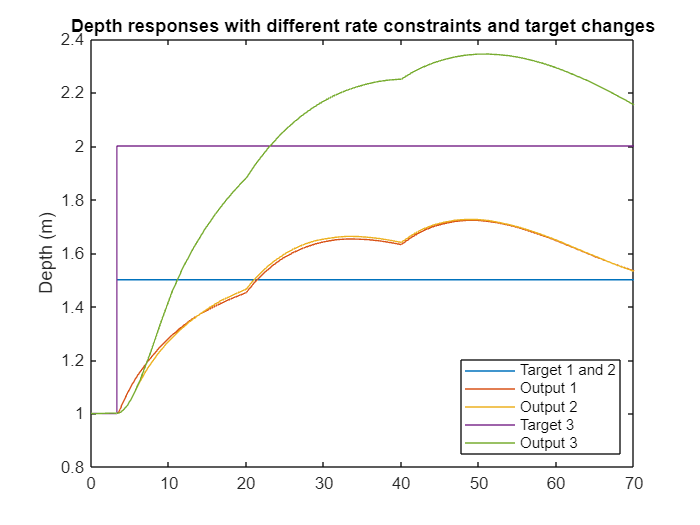

% Plotting
figure
plot(tt1/60,yy1(:,[1,4]),tt2/60,yy2(:,4),tt3/60,yy3(:,[1,4]));
legend('Target 1 and 2','Output 1','Output 2','Target 3','Output 3','Location','southeast')
title('Depth responses with different rate constraints and target changes')
ylabel('Depth (m)')

## 4. The app files

While it is possible to interact with the simulation environment using code snippets, as above, it is far more convenient to use an app interface.  Albeit this may limit what the user can change, it is a lot easier and quicker to perform compare and contrast simulations looking at the impact of different aspects. Consequently, two app interfaces have been constructed and are summarised below. 

- ***conical_tank_behaviour_control101.mlapp***

- ***conical_tank_control_control101.mlapp***

For simplicity the apps have fixed simulation times and so forth. To perform specific investigations users would need to resort to the code snippets in this file and indeed be prepared to modify the source simulink files if required.

### ***4.1 App investigating open-loop behaviours of a conical tank model: conical_tank_behaviour_control101.mlapp***

The first tab builds on section 2 above and allows users to investigate how the system behaviour changes with initial depth and tank angle. A core point is to decide what factors a user might wish to change. The linearisation point is based on the initial depth. The app allows the following changes, although only to  a relatively limited degree of precision:

- The tank angle.

- The initial depth.

- Tank outlet dimensions (in effect outlet resistance to flow); the value in the resistance slider is scaled by 1000.

- The magnitude of input flow, relative to the steady-state flow meeting the initial depth.

- The disturbance in-flow changes but not the timing (currently coded to be mid-simulation).

- The magnitude of blockage changes but not the timing (currently coded to be late-simulation).

- Buttons are used to switch the disturbance/blockage effects on and off (green means on).

Users will quickly be able to explore the differences in behaviour between the linear and non-linear models and indeed note how the non-linear behaviour changes significantly with initial depth and angle.  Users can also begin to discern the extent to which a linearised model might be useful.  The history plot in the top right keeps track of how behaviour changes with different settings so that users can undertake systematic investigations.

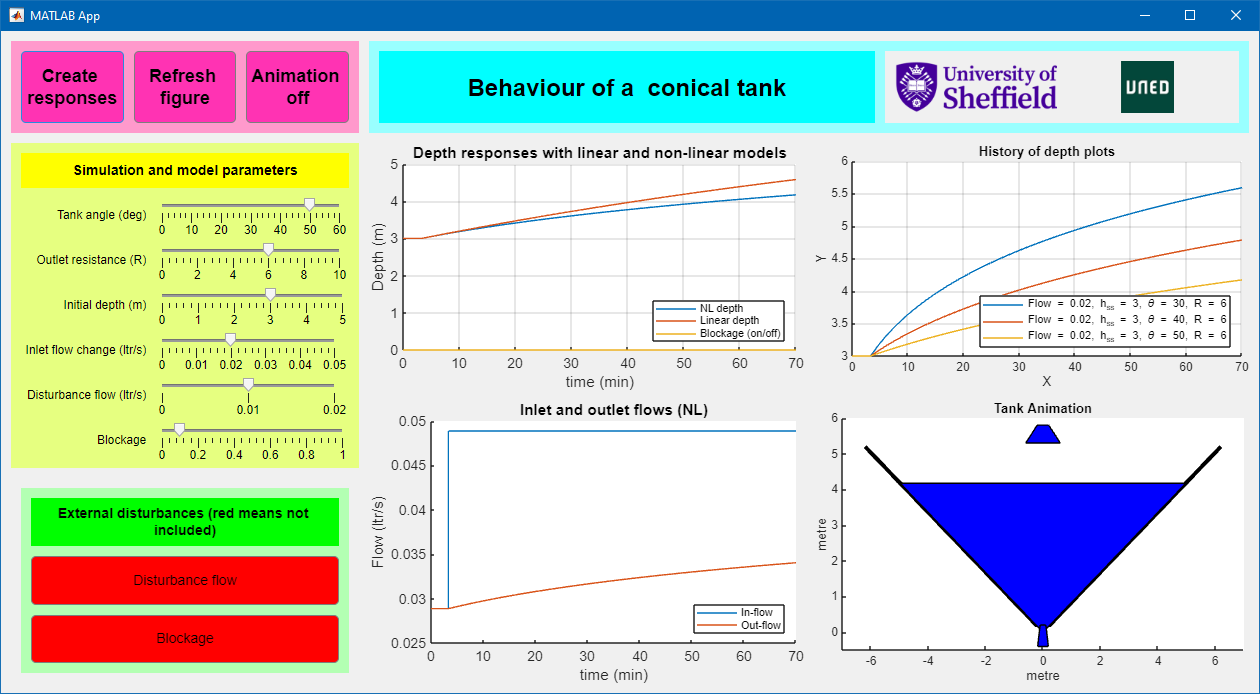

**Figure 3**. Screen dump of the app for illustration (***conical_tank_behaviour_control101.mlapp***)

### ***4.2 App investigating feedback of the non-linear tank model subject to uncertainty and constraints: conical_tank_control_control101.mlapp***

This app builds on section 2 above. A core point is to decide what factors a user might wish to change. The app allows the following changes, although only to  a relatively limited degree of precision:

- The magnitude of disturbance in-flow changes but not the timing (can be changed in source file data definitions).

- The magnitude of blockage changes but not the timing (can be changed in source file data definitions).

- The size of the input limits (absolute and rate), but only within set ranges.

- The magnitude of the measurement noise, but only within set ranges.

- The use or not of anti-windup in the PID compensator (the PID values are defined automatically as in section 2.1 so can only be edited in the source code).

These effects can also be turned off entirely using some toggle buttons in the bottom left. It is noted that anti-windup can only deployed if input saturation is activated, so these two buttons cannot always be toggled independently. The bottom right figure shows the difference between the desired PID output and that actually delivered.

The legend will keep track of core values which are not self-evident from a simulation.  A more complete single shot figure for the current simulation is available in the rigth hand column, and the history in the left column.

**Remark**: If the initial depth is increased significantly, the required time scales can increase by a factor of 20 or more as the area goes up with the square of depth!

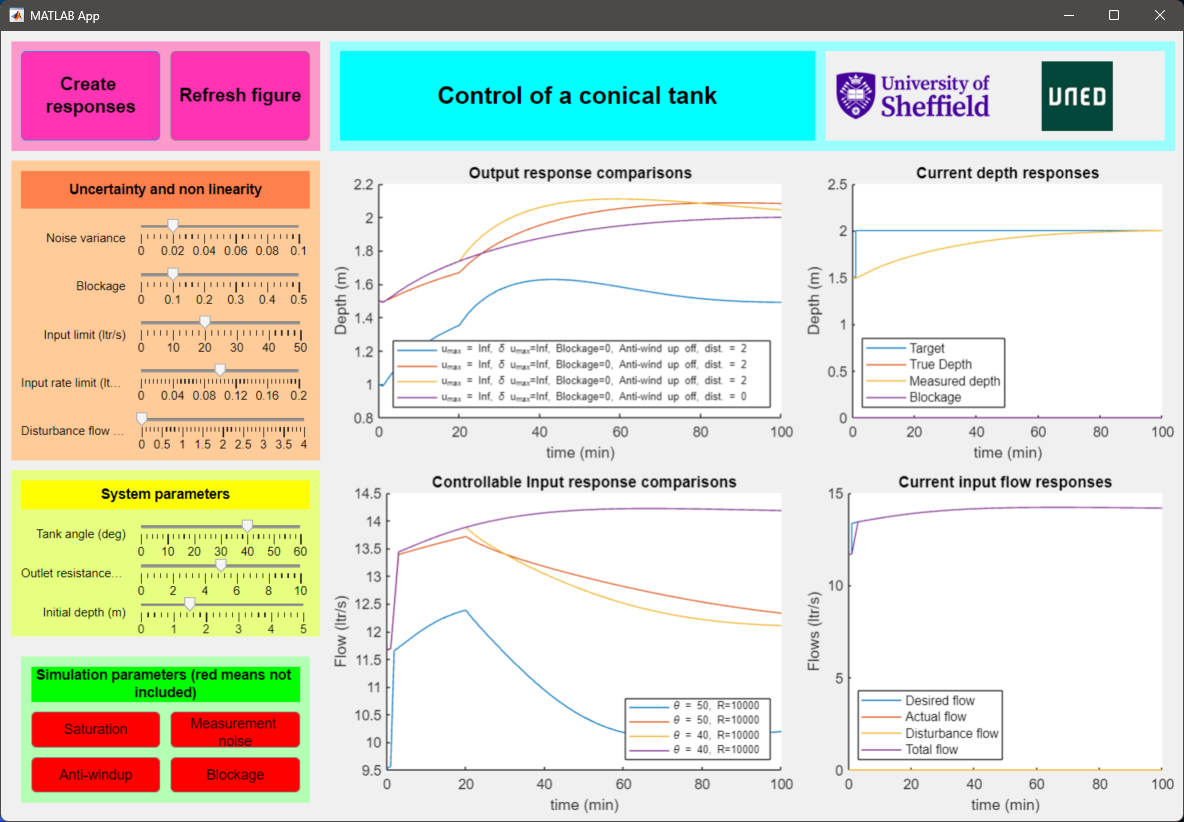

**Figure 4**. Screen dump of the app for illustration (***nonlinear_tank_control_control101.mlapp***)